# Circuit Problem 1

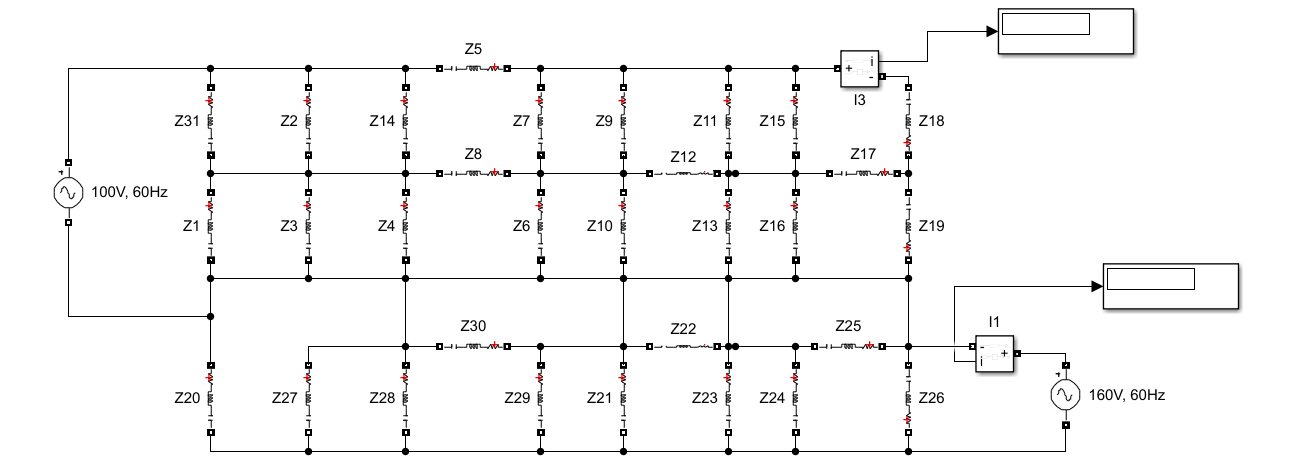

**Note - Here, we have used Adequacy of Matrix, in the last, as we were getting our matrix A to be ill conditioned**

**Solution: Using Mesh Analysis**

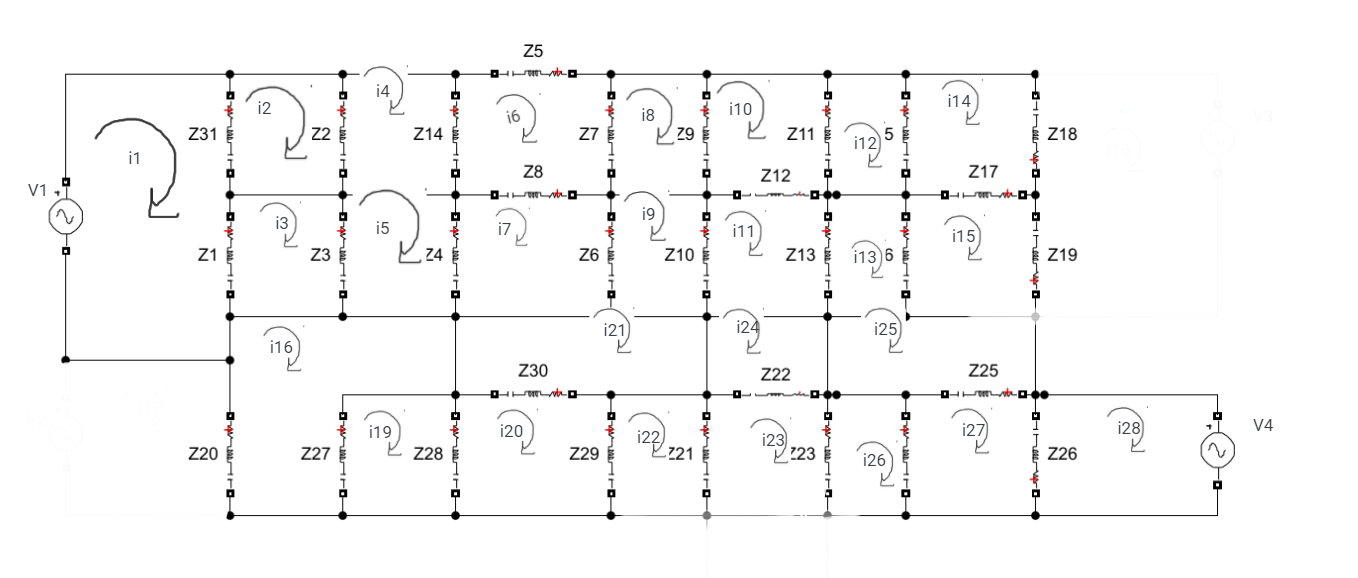

clc;
clear;
format long g;
f = 60;

R = [1671, 213, 1805, 281, 2720, 2632, 1644, 2151, 102, 1892, 517, 40, 440, 2679, 3111, 2309, 1971, 724, 1942, 2059, 380, 2061, 82, 801, 1554, 3010, 472, 1006, 3010, 472, 1006];
L = [0.42541591958320346,0.18183916308678427,0.8853769186364207,0.992479819054851,0.8061717645142782,0.3946585624142682,0.07164824915636947,0.5220757376639864,0.1009003159687697,0.6836288870623745,0.8244011181706654,0.4472345807888236,0.26653121706023286,0.4314357258078425,0.31793809892944624,0.8482655751567437,0.7921564839656123,0.2749688254625463,0.9484901063505002,0.11187486657922385,0.8156850228898229,0.9632384219236735,0.996327734605249,0.03998362219024387,0.8289993334854372,0.6030114739654502,0.861358788047135,0.5098092292157849,0.6030114739654502,0.861358788047135,0.5098092292157849];
C = [419, 88, 360, 158, 152, 142, 262, 288, 422, 321, 487, 173, 394, 299, 287, 496, 209, 452, 456, 64, 471, 44, 154, 385, 233, 462, 92, 135, 462, 92, 135];

k = 1;
Z = R(k) + (2*pi*L(k) - 1/(2*pi*f*C(k)))*1i;
for k = 2:length(R)
    Z(end+1) = R(k) + (2*pi*L(k) - 1/(2*pi*f*C(k)))*1i;
end

A(1:26,1:26) = 0;
B(1:26) = 0;

%For First Loop
A(1,1) = Z(1)+Z(31);
A(1,2) = -Z(31);
A(1,3) = -Z(1);

% for second loop of i2
A(2,1) = -Z(31);
A(2,2) = Z(2)+Z(31);
A(2,4) = -Z(2);

% for 3rd loop 
A(3,1) = -Z(1);
A(3,5) = -Z(3);
A(3,3) = Z(1)+Z(3);

% for 4th loop
A(4,1) = -Z(2);
A(4,4) = Z(14)+Z(2);
A(4,6) = -Z(14);

% for 5th loop
A(5,3) = -Z(3);
A(5,5) = Z(4)+Z(3);
A(5,7) = -Z(4);

% for 6th loop
A(6,4) = -Z(14);
A(6,6) = Z(5)+Z(7)+Z(8)+Z(14);
A(6,8) = -Z(7);
A(6,7) = -Z(8);

% for 7th loop
A(7,5) = -Z(4);
A(7,6) = -Z(8);
A(7,7) = Z(8)+Z(4)+Z(6);
A(7,9) = -Z(6);

% for 8th loop
A(8,6) = -Z(7);
A(8,10) = -Z(9);
A(8,8) = Z(7)+Z(9);

% frop 9th loop
A(9,7) = -Z(6);
A(9,11) = -Z(10);
A(9,9) = Z(6)+Z(10);

% for 10th loop
A(10,8) = -Z(9);
A(10,11) = -Z(12);
A(10,12) = -Z(11);
A(10,10) = Z(9)+Z(11)+Z(12);


% for 11th loop
A(11,9) = -Z(10);
A(11,10) = -Z(12);
A(11,13) = -Z(13);
A(11,11) = Z(10)+(12)+13;

% for 12th loop
A(12,10) = -Z(11);
A(12,14) = -Z(15);
A(12,12) = Z(11)+Z(15);

% for 13th loop
A(13,11) = -Z(13);
A(13,15) = -Z(16);
A(13,13) = Z(16) + Z(13);


% for 14th loop
A(14,12) = -Z(15);
A(14,15) = -Z(17);
A(14,16) = -Z(18);
A(14,14) = Z(15)+Z(17)+Z(18);

% for 15th loop
A(15,13) = -Z(16);
A(15,14) = -Z(17);
A(15,16) = -Z(19);
A(15,15) = Z(16)+Z(17)+Z(19);


% for 18th loop
A(16,17) = -Z(27);
A(16,15) = -Z(20);
A(16,16) = Z(27)+Z(20);

% for 19th loop
A(17,18) = -Z(28);
A(17,16) = -Z(27);
A(17,17) = Z(27)+Z(28);

% for 20th loop
A(18,17) = -Z(28);
A(18,19) = -Z(30);
A(18,20) = -Z(29);
A(18,18) = Z(28)+Z(29)+Z(30);


% for 21th loop
A(19,18) = -Z(30);
A(19,19) = Z(30);

% for 22nd loop
A(20,18) = -Z(29);
A(20,21) = -Z(21);
A(20,20) = Z(29)+Z(21);

% for 23rd loop
A(21,20) = -Z(21);
A(21,22) = -Z(22);
A(21,24) = -Z(23);
A(21,21) = Z(21) + Z(22) + Z(23);

% for 24th loop
A(22,21) = -Z(22);
A(22,22) = Z(22);

% for 25th loop
A(23,25) = -Z(25);
A(23,23) = Z(25);

% for 26th loop
A(24,21) = -Z(23);
A(24,25) = -Z(24);
A(24,24) = Z(23)+Z(24);

% for 27th loop
A(25,24) = -Z(24);
A(25,23) = -Z(25);
A(25,26) = -Z(26);
A(25,25) = Z(24)+Z(25)+Z(26);

% for 28th loop
A(26,25) = -Z(26);
A(26,26) = Z(26);

B(1) = 100;
B(26) = 160;

X = A\(B');
fprintf('Here we are getting Error, becuase Matrix is coming to be Ill Conditioned');

Here we are getting Error, becuase Matrix is coming to be Ill Conditioned

% Here we are getting Error, becuase Matrix is coming to be Ill Conditioned

%A = [ 1 2 3; 2 3 4; 4 2 1];
sumss(1:length(A), 1) = 0;
for i = 1:length(A)
    sumss(i) = sum(abs(A(i,1:length(A))));
end
norms = max(sumss)

norms =           15668.0111347161



A = inv(A);

new_sumss(1:length(A), 1) = 0;
for i = 1:length(A)
    new_sumss(i) = sum(abs(A(i,1:length(A))));
end
new_norms = max(new_sumss)

new_norms =          0.266059858054731



conditioning = norms * new_norms;
tempc = conditioning/2^(64);% Suppose this is floating point number of 23 bits mantissa
m = abs(log(tempc*2)/log(10));
fprintf(' value of m should be less than or equal to 2 for 23 bits mantissa \nbut we are getting = %f\nHence, above circuit is ill Conditioned',m);

 value of m should be less than or equal to 2 for 23 bits mantissa 
but we are getting = 15.344897
Hence, above circuit is ill Conditioned